dir = 'examples/data/mnist/';

trainFilename = [dir 'mnist_train.gz'];
trainLabelsFilename = [dir 'mnist_train_labels.gz'];
testFilename = [dir 'mnist_test.gz'];
testLabelsFilename = [dir 'mnist_test_labels.gz'];

XTrain = processImagesMNIST(trainFilename);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processLabelsMNIST(trainLabelsFilename);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest = processImagesMNIST(testFilename);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processLabelsMNIST(testLabelsFilename);


Read MNIST label data...
Number of labels in the dataset:  10000 ...



XTrain = extractdata(XTrain);
XTest = extractdata(XTest);

[trainInd, valInd, ~] = dividerand(length(XTrain), .9, .1, .0);

XVal = XTrain(:, :, :, valInd);
YVal = YTrain(valInd);
XTrain = XTrain(:, :, :, trainInd);
YTrain = YTrain(trainInd);

inputSize = [28 28];

layers = [
    imageInputLayer([inputSize 1], 'Name', 'input')
    
    convolution2dLayer([3 3], 16, 'Padding', 'same', 'Name', 'conv-1')
    reluLayer('Name', 'relu-1')
    maxPooling2dLayer([2 2], 'Name', 'max-pool-1')
    
    convolution2dLayer([3 3], 32, 'Padding', 'same', 'Name', 'conv-2')
    reluLayer('Name', 'relu-2')
    maxPooling2dLayer([2 2], 'Name', 'max-pool-2')
    
    convolution2dLayer([3 3], 64, 'Padding', 'same', 'Name', 'conv-3')
    reluLayer('Name', 'relu-3')
    maxPooling2dLayer([2 2], 'Name', 'max-pool-3')
    
    fullyConnectedLayer(10, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

miniBatchSize = 16;

options = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 4, ...
    'InitialLearnRate', .01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

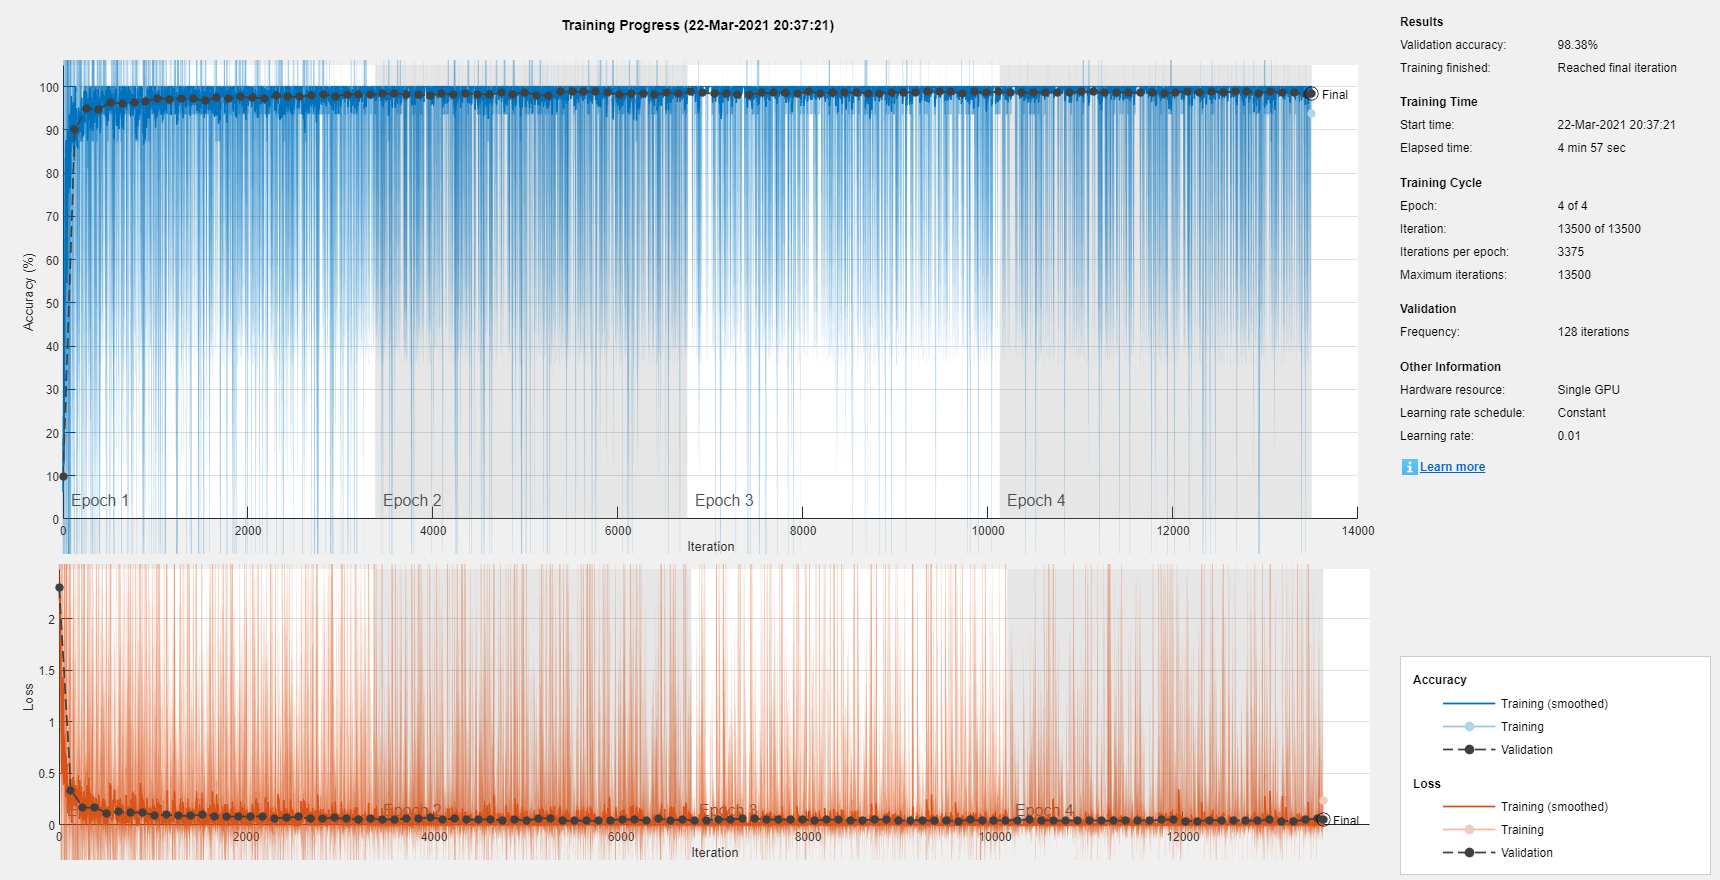

[net, info] = trainNetwork(XTrain, YTrain, layers, options);

probs = predict(net, XTest);
[~, YPred] = max(probs, [], 2);
YPred = categorical(YPred - 1);
acc = sum(YPred == YTest) / length(YTest);

fprintf("***************\n");

***************


fprintf("Accuracy: %0.3f\n", acc);

Accuracy: 0.987


fprintf("***************\n");

***************


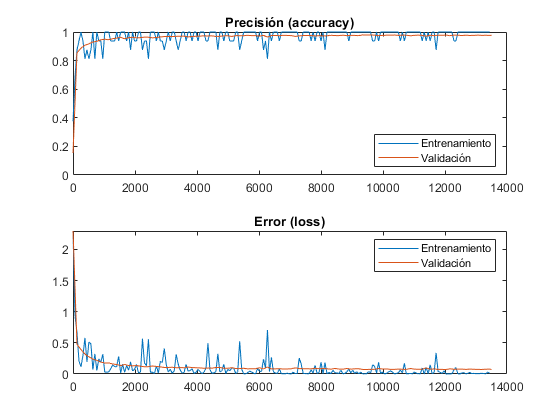

figure

subplot(2, 1, 1);

x = 1:miniBatchSize*4:length(info.TrainingAccuracy);
trainAcc = info.TrainingAccuracy(x) / 100;
plot(x, trainAcc);
hold on

x = find(~isnan(info.ValidationAccuracy));
valAcc = info.ValidationAccuracy(x) / 100;
plot(x, valAcc);

legend({'Entrenamiento', 'Validación'}, 'Location', 'southeast');
title('Precisión (accuracy)');
yticks(0:.2:1);

subplot(2, 1, 2);

x = 1:miniBatchSize*4:length(info.TrainingLoss);
trainLoss = info.TrainingLoss(x);
plot(x, trainLoss);
hold on

x = find(~isnan(info.ValidationLoss));
valLoss = info.ValidationLoss(x);
plot(x, valLoss);

legend({'Entrenamiento', 'Validación'});
title('Error (loss)');

mnistCNN = net;
save mnistCNN